# Part 1: Step 1


snr_db = zeros(1,10);
snr = zeros(1, 10);         
bit_errors = zeros(1, 10);  
block_errors = zeros(1, 10);
symbol_errors = zeros(1, 10)

symbol_errors =      0     0     0     0     0     0     0     0     0     0



for i = 1:10
    snr_db(i) = 4 + i;           
    snr(i) = 10.^(snr_db(i)/10); 
    n_loops = 0;         
    n_symbol_errors = 0; 
    n_bit_errors = 0;    
    n_block_errors = 0;

%step 2
    while n_symbol_errors < 100

        tx_signal = 2 * (rand(100, 1) > 0.5) - 1;
        noise = 1/sqrt(snr(i))*randn(100,1);
        rx_signal = tx_signal+noise;
        rx_decoded = sign(rx_signal);
        cur_n_symbol_errors = sum(rx_decoded ~= tx_signal);
  
        n_symbol_errors = n_symbol_errors + cur_n_symbol_errors;
        n_bit_errors= n_symbol_errors;
        if(cur_n_symbol_errors>0)
            n_block_errors = n_block_errors+1;
        end
        n_loops=n_loops+1;
    end 

% step 3    
    symbol_errors(i)=n_symbol_errors/(n_loops*100);
    disp(i);
    bit_errors(i)=n_bit_errors/(n_loops*100);
    disp(i);
    block_errors(i)=n_block_errors/n_loops;
    disp(i);
end

     1



     1



     1



     2



     2



     2



     3



     3



     3



     4



     4



     4



     5



     5



     5



     6



     6



     6



     7



     7



     7



     8



     8



     8



     9



     9



     9




semilogy(snr_db,bit_errors,snr_db,block_errors,'--');
legend('Bit Error Rate','Block Error Rate (100bits)') 
xlabel(' SNR (dB)')
ylabel('Error Rate')
grid

% disp(i) just show the position of for loop
% block error is much higher than symbol error because we didn't devide
% n_block_errors by loops*100, other devide by 100 because bit rate



## Part 2

QPSK = [1+1j, 1-1j, -1+1j, -1-1j];
snr_db = zeros(1,10);
snr = zeros(1, 10);         
bit_errors = zeros(1, 10);  
block_errors = zeros(1, 10);
symbol_errors = zeros(1, 10);
% Initialize arrays for real and imaginary error counts
real_errors = zeros(1, 10);
imag_errors = zeros(1, 10);

for i = 1:10
    snr_db(i) = 4 + i;           
    snr(i) = 10.^(snr_db(i)/10); 
    n_loops = 0;         
    n_symbol_errors = 0; 
    n_bit_errors = 0;    
    n_block_errors = 0;
    n_real_errors=0;
    n_imag_errors=0;
%step 2
    while n_symbol_errors < 100
        QPSK_indices=ceil(4*rand(100, 1));

        tx_signal = QPSK(QPSK_indices);
        noise = 1/sqrt(snr(i))*(randn(1,100) + 1j*randn(1,100));
        rx_signal = tx_signal+noise;
        
        decode_real = sign(real(rx_signal));
        decode_imag = sign(imag(rx_signal));
        
        real_part_errors = decode_real ~= real(tx_signal);
        imag_part_errors = decode_imag ~= imag(tx_signal);
        

        n_bit_errors = sum(real_part_errors)+sum(imag_part_errors);
        cur_n_symbol_errors = sum(real_part_errors | imag_part_errors);
        n_symbol_errors = n_symbol_errors + cur_n_symbol_errors;
        n_block_errors = n_block_errors + sign(cur_n_symbol_errors);
        n_loops=n_loops+1;
    end 

% step 3    
    
    real_errors(i) = n_real_errors;
    imag_errors(i) = n_imag_errors;

    symbol_errors(i)=n_symbol_errors/(n_loops*100);
    bit_errors(i)=n_bit_errors/(n_loops*200);
    block_errors(i)=n_block_errors/n_loops;
    disp(i);
end

semilogy(snr_db,symbol_errors,snr_db,bit_errors,'--',snr_db,block_errors,'-o')
legend('Symbol Error Rate','Bit Error Rate','Block Error Rate (100bits)');
xlabel(' SNR (dB)')
ylabel('Error Rate')
grid

% How much did the curve shift from your BPSK version?
% Block error curve shift down, bit error doesn't change

%  After 10 dB SNR how quickly does the curve decrease per 1 dB?
% from 8.29e-06 to 2.04e-06, about 2/3 10^-1

## Part 3

QPSK = [1+1j, 1-1j, -1+1j, -1-1j];
snr_db = zeros(1,10);
snr = zeros(1, 10);         
bit_errors = zeros(1, 10);  
block_errors = zeros(1, 10);
symbol_errors = zeros(1, 10);
% Initialize arrays for real and imaginary error counts
real_errors = zeros(1, 10);
imag_errors = zeros(1, 10);
v=0.3;
fd=(v*2*10^9)/(3.8*10^10);
snr_a_db=zeros(1,10);
snr_a=0;

for i = 1:10
    snr_db(i) = 4 + i;           
    snr(i) = 10.^(snr_db(i)/10); 
    n_loops = 0;         
    n_symbol_errors = 0; 
    n_bit_errors = 0;    
    n_block_errors = 0;
    n_real_errors=0;
    n_imag_errors=0;
%step 2
    while n_symbol_errors < 10000
        alpha = Jakes(0.5, 1, fd);
        snr_a = snr_a + mean(abs(alpha).^2)*snr(i);

        QPSK_indices=ceil(4*rand(100, 1));

        tx_signal = QPSK(QPSK_indices);
        noise = 1/sqrt(snr(i))*(randn(1,100) + 1j*randn(1,100));
        rx_signal = alpha.'.*tx_signal;
        rx_signal = rx_signal + noise;
        
        decode_real = sign(real(rx_signal./alpha.'));
        decode_imag = sign(imag(rx_signal./alpha.'));
        
        real_part_errors = decode_real ~= real(tx_signal);
        imag_part_errors = decode_imag ~= imag(tx_signal);
        

        n_bit_errors = sum(real_part_errors)+sum(imag_part_errors);
        cur_n_symbol_errors = sum(real_part_errors | imag_part_errors);
        n_symbol_errors = n_symbol_errors + cur_n_symbol_errors;
        n_block_errors = n_block_errors + sign(cur_n_symbol_errors);
        n_loops=n_loops+1;
    end 

% step 3    
    
    real_errors(i) = n_real_errors;
    imag_errors(i) = n_imag_errors;

    symbol_errors(i)=n_symbol_errors/(n_loops*100);
    bit_errors(i)=n_bit_errors/(n_loops*200);
    block_errors(i)=n_block_errors/n_loops;
    disp(i);
    snr_a_db(i) = 10*log10(snr_a / n_loops);
end

semilogy(snr_db,symbol_errors,snr_db,bit_errors,'--',snr_a_db,block_errors,'-o')
legend('Symbol Error Rate','Bit Error Rate','Block Error Rate (100bits)');
xlabel(' SNR (dB)')
ylabel('Error Rate')
grid

%delete old part 3

frame_time = zeros(1, 100)

frame_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:100
    frame_time(i) = (5e-5)*(i-1);
end
n_echoes = 1;
f_doppler = (0.3*2000/3.8e10);
snr_a_db = zeros(1,10);
snr_a = 0;

QPSK = [1+1j, 1-1j, -1+1j, -1-1j];
snr_db = zeros(1,10);
snr = zeros(1, 10);         
bit_errors = zeros(1, 10);  
block_errors = zeros(1, 10);
symbol_errors = zeros(1, 10);
% Initialize arrays for real and imaginary error counts
real_errors = zeros(1, 10);
imag_errors = zeros(1, 10);
v=300000;
fd=(v*2*10^9)/(3.8*10^10);
snr_a_db=zeros(1,10);
snr_a=0;

for i = 1:10
    snr_db(i) = 4 + i;           
    snr(i) = 10.^(snr_db(i)/10); 
    n_loops = 0;         
    n_symbol_errors = 0; 
    n_bit_errors = 0;    
    n_block_errors = 0;
    n_real_errors=0;
    n_imag_errors=0;
%step 2
    while n_symbol_errors < 10000
        alpha = Jakes(frame_time, 1, fd);
        snr_a = snr_a + mean(abs(alpha).^2)*snr(i);

        QPSK_indices=ceil(4*rand(100, 1));

        tx_signal = QPSK(QPSK_indices);
        noise = 1/sqrt(snr(i))*(randn(1,100) + 1j*randn(1,100));
        rx_signal = alpha.'.*tx_signal;
        rx_signal = rx_signal + noise;
        
        decode_real = sign(real(rx_signal./alpha.'));
        decode_imag = sign(imag(rx_signal./alpha.'));
        
        real_part_errors = decode_real ~= real(tx_signal);
        imag_part_errors = decode_imag ~= imag(tx_signal);
        

        n_bit_errors = n_bit_errors + sum(real_part_errors)+sum(imag_part_errors);
        cur_n_symbol_errors = sum(real_part_errors | imag_part_errors);
        n_symbol_errors = n_symbol_errors + cur_n_symbol_errors;
        n_block_errors = n_block_errors + sign(cur_n_symbol_errors);
        n_loops=n_loops+1;
    end 

% step 3    
    
    real_errors(i) = n_real_errors;
    imag_errors(i) = n_imag_errors;

    symbol_errors(i)=n_symbol_errors/(n_loops*100);
    bit_errors(i)=n_bit_errors/(n_loops*200);
    block_errors(i)=n_block_errors/n_loops;
    disp(i);
    snr_a_db(i) = 10*log10(snr_a / n_loops);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



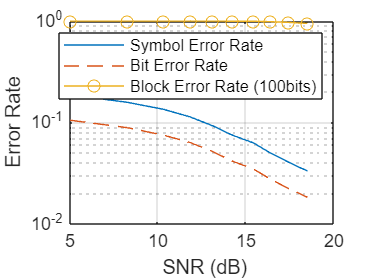


semilogy(snr_a_db,symbol_errors,snr_a_db,bit_errors,'--',snr_a_db,block_errors,'-o')
legend('Symbol Error Rate','Bit Error Rate','Block Error Rate (100bits)');
xlabel(' SNR (dB)')
ylabel('Error Rate')
grid